# Let's Plot a GMM

## Define the GMM

We first specify an array of GMM component structs.

c1 = struct('mu', [2 2]', 'sigma', eye(2,2));
c2 = struct('mu', [4 3]', 'sigma', 0.1*[4 0; 0 36]);
theGMM = [c1; c2];

## Compute the GMM Surface

Now we compute the height of the curve over a surface.

xAxis = 1:0.1:5;
yAxis = 1:0.1:5;
[X,Y,Z] = GMM2DGrid(xAxis, yAxis, theGMM);

## Plot It

Now, let's plot it.

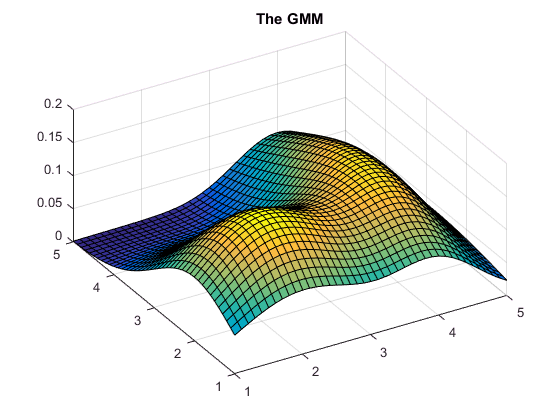

surf(X,Y,Z)
view([-30.700 49.200])
title('The GMM')

You can add links: [AMPD](http://wiki.dac.us/pages/viewpage.action?title=AMPD&spaceKey=AMPD).

And you can add images and equations (either MATLAB style or LaTeX)...


$$y=x^2$$